# Final Project First Course

Harvey became a hurricane August 24th, made landfall on the 25th, and was downgraded to a tropical storm on August 26th.

The impact of Harvey was felt over much more than just 3 days. In the 2017 storm events data set, Harvey related events are reported beginning August 17th and end September 3rd as the system moved north and east across the United States. Flooding, thunderstorms, hail, and tornadoes are just a few of the weather events related to Harvey.

Made by: CARLOS ITURBE GIL

## Background and Scope

### Import the Data

Use only the first time to generate the function

%uiimport("StormEvents_2017_finalProject.csv")
%pause

Use in anytime later of using uiimport command

clc
clear
ev=importfile1("StormEvents_2017_finalProject.csv");
ev.Property_Cost(ismissing(ev.Property_Cost))=0;
head(ev,10)

ans = 10×24 table
    EpisodeID      Event_ID         State         Year     Month            Event_Type                              CZ_Name                          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                          

### Two States Most Impacted by Harvey

Clearly state the two states in order 

hb=datetime("2017-08-17 00:00:00");
he=datetime("2017-09-03 11:59:59");
hb1=day(hb,"dayofyear");
he1=day(he,"dayofyear");
ev1=ev;
ev1=ev1(day(ev1.Begin_Date_Time,"dayofyear")>= hb1 & day(ev1.End_Date_Time,"dayofyear") <= he1,:);
ev2=groupsummary(ev1,"State","Sum","Property_Cost");
ev2 = sortrows(ev2,'sum_Property_Cost','descend')

ev2 = 57×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                272           7.7427e+10    
    LOUISIANA             85           7.5277e+07    
    NORTH CAROLINA        59           1.2339e+07    
    WASHINGTON             2                4e+06    
    FLORIDA               68            2.237e+06    
    MINNESOTA             24            1.375e+06    
    NEBRASKA              62            1.054e+06    
    MISSISSIPPI           39             9.15e+05    
    NEW YORK             109             6.41e+05    
    TENNESSEE             46             5.04e+05    
    PENNSYLVANIA         203           4.9163e+05    
    KENTUCKY              20             4.35e+05    
    CALIFORNIA            74             3.29e+05    
    IOWA                  54             3.21e+05    
    INDIANA     

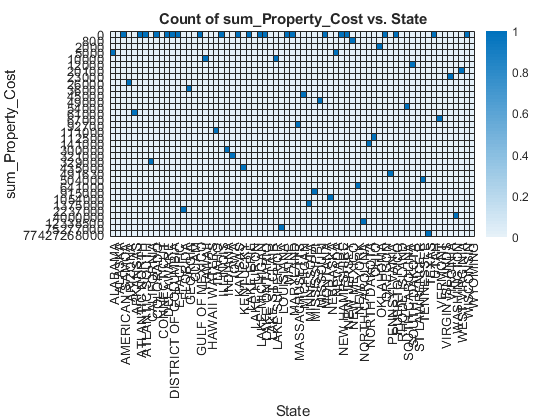

heatmap(ev2,"State","sum_Property_Cost")

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

ev3=ev1;
ev4=ev1;
ev3=ev3(ev3.State=="TEXAS",:);
ev31=groupsummary(ev3,"Event_Type");
ev31 = sortrows(ev31,'GroupCount','descend')

ev31 = 11×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             126    
    Tropical Storm           41    
    Thunderstorm Wind        27    
    Tornado                  26    
    Flood                    16    
    Heat                     13    
    Hurricane                 9    
    Storm Surge/Tide          6    
    Funnel Cloud              3    
    Hail                      3    
    Heavy Rain                2    


ev4=ev4(ev4.State=="LOUISIANA",:);
ev41=groupsummary(ev4,"Event_Type");
ev41 = sortrows(ev41,'GroupCount','descend')

ev41 = 6×2 table
       Event_Type       GroupCount
    ________________    __________

    Flash Flood             53    
    Heat                    17    
    Tornado                  7    
    Storm Surge/Tide         4    
    Tropical Storm           3    
    Flood                    1    


## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

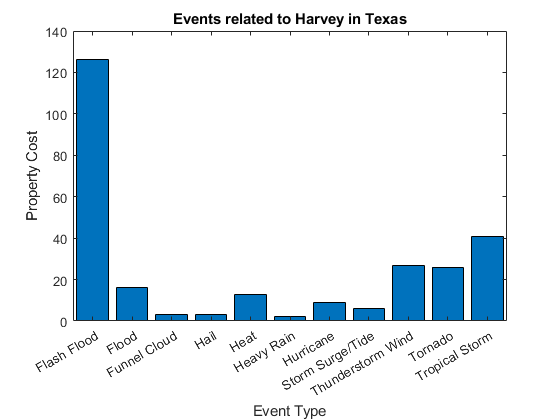

ev31.Event_Type=removecats(ev31.Event_Type);
bar(ev31.Event_Type,ev31.GroupCount)
title("Events related to Harvey in Texas")
xlabel("Event Type")
ylabel("Property Cost")

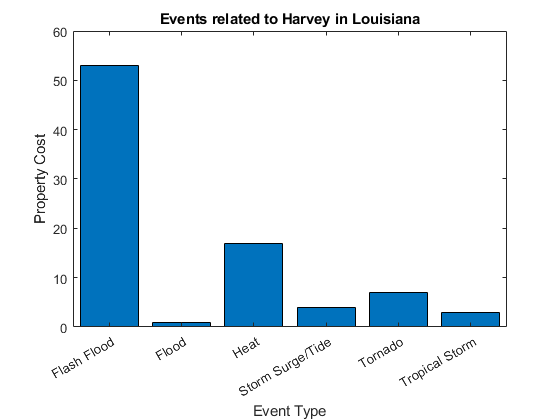

ev41.Event_Type=removecats(ev41.Event_Type);
bar(ev41.Event_Type,ev41.GroupCount)
title("Events related to Harvey in Louisiana")
xlabel("Event Type")
ylabel("Property Cost")

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

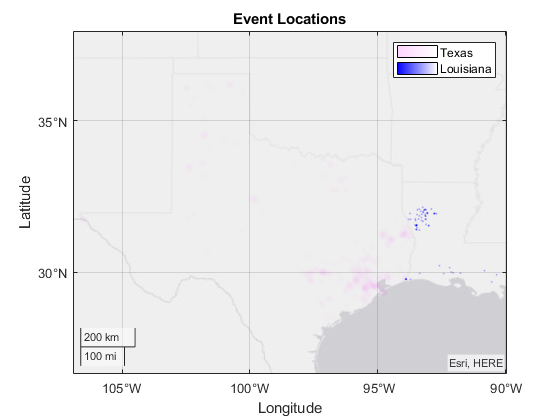

geodensityplot(ev3.Begin_Lat,ev3.Begin_Lon,'FaceColor','m');
hold on
geodensityplot(ev4.Begin_Lat,ev4.Begin_Lon,'FaceColor','b');
title("Event Locations")
legend("Texas","Louisiana")
geolimits("auto")
hold off

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

ev32=groupsummary(ev3,"CZ_Name");
ev32 = sortrows(ev32,'GroupCount','descend');
head(ev32,3)

ans = 3×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    


### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

ev42=groupsummary(ev4,"CZ_Name");
ev42 = sortrows(ev42,'GroupCount','descend');
head(ev42,3)

ans = 3×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    


### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest property damage in state 1. *Be sure to include the dollar amount*. 

ev33=groupsummary(ev3,"CZ_Name","Sum","Property_Cost");
ev33 = sortrows(ev33,'sum_Property_Cost','descend');
head(ev33,3)

ans = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    


### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest property damage in state 2. *Be sure to include the dollar amount*. 

ev43=groupsummary(ev4,"CZ_Name","Sum","Property_Cost");
ev43 = sortrows(ev43,'sum_Property_Cost','descend');
head(ev43,3)

ans = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     


## Conclusions and Recommendations

According to the results the two most impacted states are Texas and Louisiana, different type events presents like flash flood, tornados, tropical storm, heat etc. 

In Texas the three most impacted counties are dfferent to the three counties with the most property damage, in fact we have Galvestone, Fort Bend and Montgomery respectively 

In Lousiana  something similar occurs, the three counties with the most property damage are Calcasieu, Beauregard and Acadia respectively

This couinties mentioned before require the most possible atention 